# Rail under slow chaotic shaking

 The system is shown pictorially :

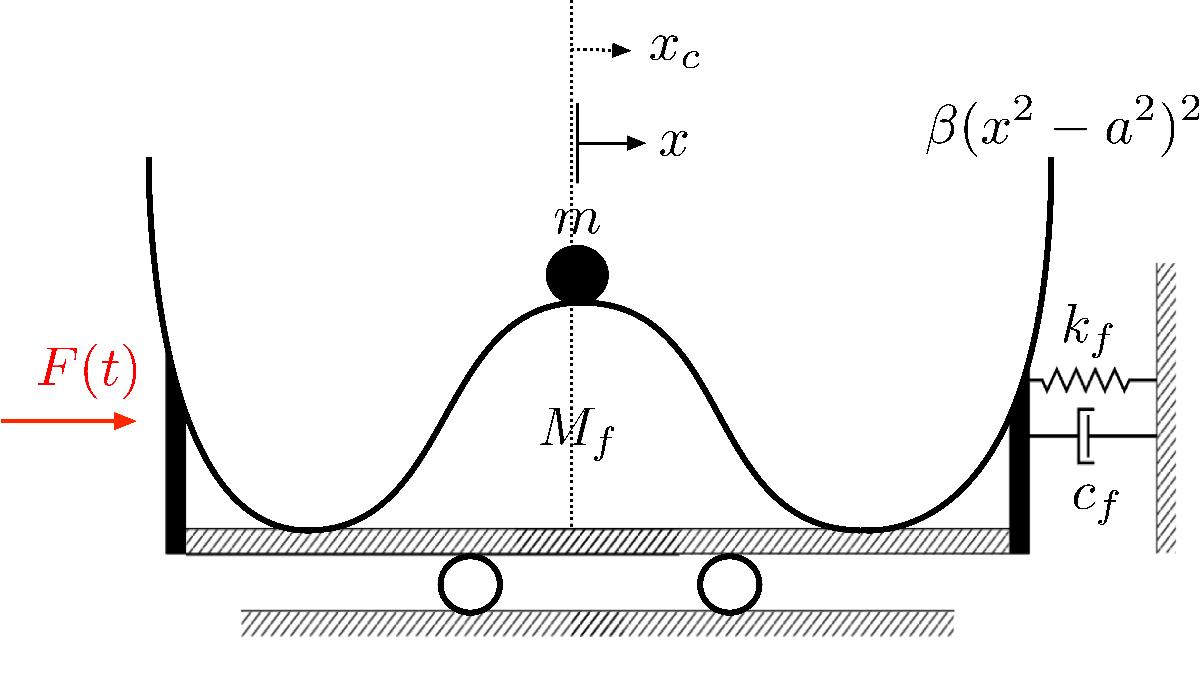

The forcing is easier to express when one moves to the center of mass coordinates and the relative displacement coordinates of the smaller blocks. Further we shift the centre of mass coordinates to make the origin the fixed point. The system is described as : 


$$\mathbf{M}={\scriptscriptstyle \left(\begin{array}{cc}
M_{f}+m & 0\\
0 & \frac{mM_{f}}{m+M_{f}}
\end{array}\right)},\quad\mathbf{K}={\scriptstyle \left(\begin{array}{cc}
k_{f} & -k_{f}\frac{m}{M_{f}+m}\\
-k_{f}\frac{m}{M_{f}+m} & -4\beta a^{2}mg+k_{f}\frac{m^{2}}{(M_{f}+m)^{2}}
\end{array}\right)},$$


$\mathbf{C}={\scriptstyle \left(\begin{array}{cc}
c_{f} & -c_{f}\frac{m}{M_{f}+m}\\
-c_{f}\frac{m}{M_{f}+m} & c+c_{f}\frac{m^{2}}{(M_{f}+m)^{2}}
\end{array}\right)},\quad\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})={\scriptstyle \left(\begin{array}{c}
0\\
4g\beta mx^{3}+16m\beta^{2}a^{4}x\dot{{x}}^{2}
\end{array}\right)},$ and 


$$\mathbf{F}(t)={\scriptscriptstyle \left(\begin{array}{c}
(m+M_{f})g(t)\\
0
\end{array}\right)}.$$


The signal $g(\alpha)$ is generated using the initial condition $[0.8;0.3;0.2]$ and is scaled by a factor of 10. The system paramters and forcing are generated below: 

clear all

c = 0.3;
k = 1;
a = 0.5;
g = 9.8;
m = 1;
Mf = 4;
cf = 0.3;
scale = 10*a^3;%2*a^3;
Sc = scale;
K = -[-k,k*m/(m+Mf);k*m/(m+Mf),4*a^2*m*g/scale-k*m^2/(m+Mf)^2];
C = -[-c,c*m/(m+Mf);c*m/(m+Mf),-cf-c*m^2/(m+Mf)^2];
M = [m+Mf,0;0,m*Mf/(m+Mf)];



n = 2;
F3 = sptensor([n,n,n,n]);
F2 = sptensor([n,n,n]);
F3(2,2,2,2) = 4*g*m/scale;
%F3(2,2,4,4) = 16*m*a^4;

fnl = {F2,F3};


n = length(M);
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 2


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 4


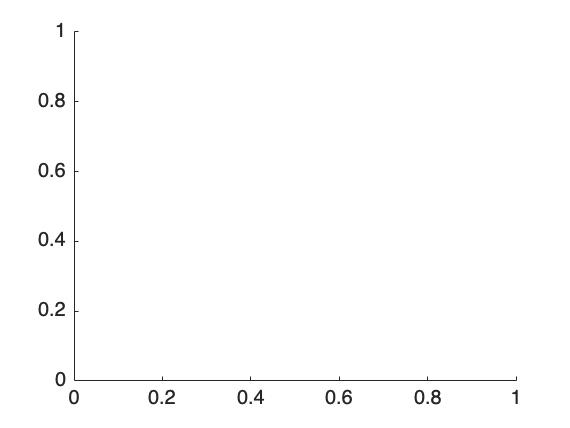



%%
% DS set up - SSM tool
hold on

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',6,'Nmax',10,'notation','multiindex')
[V,D,W] = DS.linear_spectral_analysis();


 The first 4 nonzero eigenvalues are given as 
   2.9342 + 0.0000i
  -0.0303 + 0.4473i
  -0.0303 - 0.4473i
  -3.3236 + 0.0000i



D

D =    2.9342 + 0.0000i
  -0.0303 + 0.4473i
  -0.0303 - 0.4473i
  -3.3236 + 0.0000i


S = SSM(DS);
resonant_modes = [1 2];
Acheck = V*diag(D)*inv(V);
VI = inv(V);

tic
[F, lambda, V, G, DG] = functionFromTensors(M, C, K, fnl);
toc

Elapsed time is 3.629964 seconds.



%Lorenz force 
%%

L = -20;
N_Max = 10000;
tspan = linspace(L,20,N_Max);
loren = @(t,y) lorenz_3D(t,y);
IC = [0.8;0.3;0.2];
[tk,yy] = ode45(loren,tspan,IC);

sigma = 10;
rho = 28;
beta = 8/3;

% F_a = -(sigma*rho*yy(:,1) - sigma*yy(:,1).*yy(:,3) - sigma*yy(:,2) - sigma^2*yy(:,2) + sigma^2*yy(:,1));
scaling = 3;
F_a_new = scaling*yy(:,1)/max(abs(yy(:,1)));


Force_Lorenz = griddedInterpolant(tspan(:),F_a_new(:),'spline');



fig = figure

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


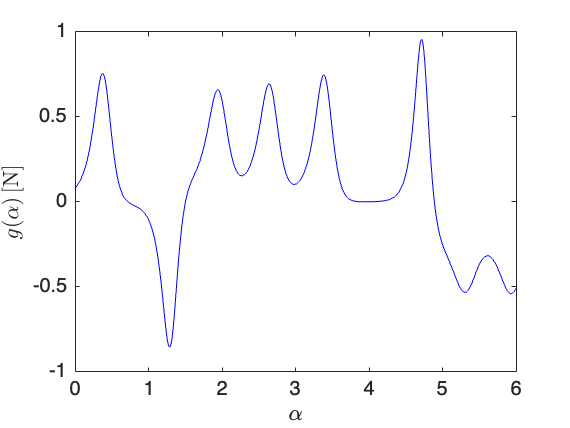

plot(tk,F_a_new/scaling,'Color','blue')
xlabel('$\alpha$','Interpreter','latex');
ylabel('$g(\alpha) \,[$N$]$','Interpreter','latex');
axis([0 6 -1 1])

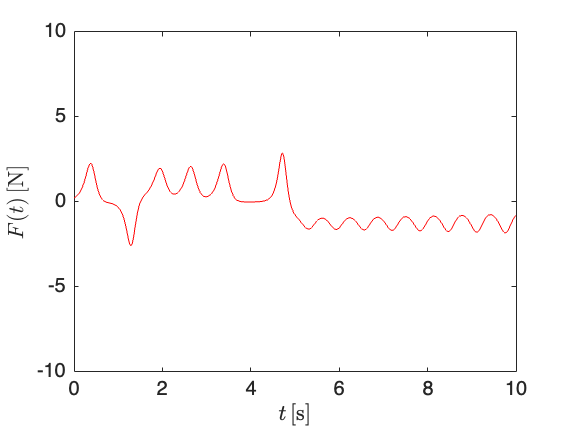


pos_t = find(tk>=0);
figure
plot(tk(pos_t),F_a_new(pos_t),'Color','red')
xlabel('$t \,[$s$]$','Interpreter','latex');
ylabel('$F(t) \,[$N$]$','Interpreter','latex');
axis([0 10 -10 10])

Setting up the $\alpha$- dependent family of eigenvectors and the critical manifold of mixed stability type.

[Vcheck,Dcheck] = eig(full(Acheck));
dsa = diag(Dcheck);
[d,ind]=sort(real(dsa));
Ds=Dcheck(ind,ind);         %sorted eigenvalue matrix
Vs=Vcheck(:,ind); 
Drot = diag(Ds);
Df = [Drot(4);Drot(1);Drot(2);Drot(3)];
Vs = [Vs(:,4),Vs(:,1),Vs(:,2),Vs(:,3)];

V0 = Vs;
flag1 =0;
if flag1 == 1
 N_grid = 1000;
Grid_F = linspace(-max(F_a_new),max(F_a_new),N_grid);
VT = cell(1,N_grid);
DT = cell(1,N_grid);
ICTT = cell(1,N_grid);
AT = cell(1,N_grid);
for i = 1:N_grid
load_vector = [Grid_F(i);0];
IC = getStaticResponse(K, M, F, load_vector, 0, 0);
ICTT{1,i} = IC(1:n,1);
[K_shift,fnl_shift] = build_model_shift(K,fnl,IC(1:n,1));
DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K_shift,'fnl',fnl_shift);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
[V,D,W] = DS.linear_spectral_analysis();
AT{1,i} = DS.BinvA;


% VC = reorient_complex(V,V0);

[Vcheck,Dcheck] = eig(full(AT{1,i}));

dsa = diag(Dcheck);
[d,ind]=sort(real(dsa));
Ds=Dcheck(ind,ind);         %sorted eigenvalue matrix
Vs=Vcheck(:,ind); 
Drot = diag(Ds);
Df = [Drot(4);Drot(1);Drot(2);Drot(3)];
Vs = [Vs(:,4),Vs(:,1),Vs(:,2),Vs(:,3)];

 VC = reorient_complex(Vs,V0);
 inv(VC)
% V0 = VC;
% [V,DA] = eigs(AT{1,i});
% dsa = diag(DA);
% [d,ind]=sort(real(-dsa));
% Ds=DA(ind,ind)          %sorted eigenvalue matrix
% Vs=V(:,ind);
VT{1,i} = VC;
DT{1,i} = Df;


end    
A = eye(4);
 save('VSP.mat','VT','V','Grid_F');
 save('ASP.mat','AT','A','Grid_F');
 save('DSP.mat','DT','Grid_F');
 save('ICSP.mat','ICTT','Grid_F');
end


 load('VSP.mat','VT','V','Grid_F');
 load('ASP.mat','AT','A','Grid_F');
 load('DSP.mat','DT','Grid_F');
 load('ICSP.mat','ICTT','Grid_F');


VarA = [];
AarA = [];
DarA = [];
IarA = [];
for ind = 1:max(size(Grid_F))
VarA = [VarA,VT{1,ind}(:)];
AarA = [AarA,full(AT{1,ind}(:))];
DarA = [DarA,DT{1,ind}(:)];
IarA = [IarA,ICTT{1,ind}(:)];
end    


ValphaR = griddedInterpolant(Grid_F(:),real(VarA).','spline');
ValphaI = griddedInterpolant(Grid_F(:),imag(VarA).','spline');
Valpha = @(F,V) reshape((ValphaR(F) + 1i*ValphaI(F)).',max(size(V(:,1))),max(size(V(1,:))));

Aalpha = griddedInterpolant(Grid_F(:),AarA.','spline');
Aalph = @(F,A) reshape(Aalpha(F).',max(size(A(:,1))),max(size(A(1,:))));

Dalpha = griddedInterpolant(Grid_F(:),DarA.','spline');
Dalph = @(F) Dalpha(F);

Ialpha = griddedInterpolant(Grid_F(:),IarA.','spline');
Ialph = @(F) Ialpha(F);

The anchor trajectory is calculated to O(3). The non-zero anchor trajectory at various orders are saved. If you wish to recompute these please set flag to 1. 


flag =1;

if flag ==1
%Order 0
xi_0 = @(alpha) [Ialpha(Force_Lorenz(alpha)).';0;0];
Load_Check = Ialph(F_a_new).';
[dXdF, Xtrunc,tkr1] = ftd(Load_Check, tk.');
IDalpha = griddedInterpolant(tkr1(:),dXdF.','spline');

ParA = [];
for gen_f = 1:max(size(F_a_new))
    P = Valpha(F_a_new(gen_f),V);
    ParA = [ParA,P(:)];
end    
[dXdFr, Xtruncr,tkr1] = ftd(real(ParA), tk.');
[dXdFi, Xtrunci,tkr1] = ftd(imag(ParA), tk.');
VDalphaR = griddedInterpolant(tkr1(:),dXdFr.','spline');
VDalphaI = griddedInterpolant(tkr1(:),dXdFi.','spline');
ValphaD = @(F,V) reshape((VDalphaR(F) + 1i*VDalphaI(F)).',max(size(V(:,1))),max(size(V(1,:))));

% [dXdFPa, XtruncPa,F_truncPa] = ftd(F_a_new.', tk.');
%  
% DForce_Lorenz = griddedInterpolant(F_truncPa(:),dXdFPa(:),'spline');

xi_1 = @(alpha,A) (inv(Aalph(Force_Lorenz(alpha),A))*[IDalpha(alpha).';0;0]);
XI_1 = [];
for indf = 1:max(size(tkr1))
    vec1=xi_1(tkr1(indf),A);
    XI_1 = [XI_1,vec1];
end    

% % Order 2 
% 
[dXdF, Xtrunc,tkr2] = ftd(XI_1, tkr1);
xi_1D = griddedInterpolant(tkr2(:),dXdF.','spline');
wrap = @(a,x)a(x);
xi_21 = @(alpha,A) wrap(xi_1(alpha,A),2);
xi_20 = @(alpha) wrap(xi_0(alpha),2);
xi_41 = @(alpha,A) wrap(xi_1(alpha,A),4);

xi_2 = @(alpha,A) (inv(Aalph(Force_Lorenz(alpha),A))*(xi_1D(alpha).'-[0;0;0;(m+Mf)/(m*Mf)*(-4*g*m*3*xi_20(alpha)*xi_21(alpha,A)^2/scale-16*m*a^4*xi_20(alpha)*xi_41(alpha,A)^2/scale^2)]));

XI_2 = [];
for indf = 1:max(size(tkr2))
    vec1=xi_2(tkr2(indf),A);
    XI_2 = [XI_2,vec1];
end 

% Order 3
[dXdF, Xtrunc,tkr3] = ftd(XI_2, tkr2);
xi_2D = griddedInterpolant(tkr3(:),dXdF.','spline');
xi_22 = @(alpha,A) wrap(xi_2(alpha,A),2);
xi_42 = @(alpha,A) wrap(xi_2(alpha,A),4);

xi_3 = @(alpha,A) (inv(Aalph(Force_Lorenz(alpha),A))*(xi_2D(alpha).'-[0;0;0;(Mf+m)/(Mf*m)*...
    (-4*g*m/scale*(xi_21(alpha,A)^3 + 6 * xi_20(alpha)*xi_21(alpha,A)*xi_22(alpha,A)) - ...
    16*m*a^4/scale^2*(xi_21(alpha,A)*xi_41(alpha,A)^2 + 2*xi_20(alpha)*xi_41(alpha,A)*xi_42(alpha,A) ))]));

XI_3A = [];
check_2D = [];
for indf = 1:max(size(tkr3))
    vec1=xi_3(tkr3(indf),A);
    check_2D = [check_2D,xi_1D(tkr3(indf)).'];
    XI_3A = [XI_3A,vec1];
end 

XI_2A = [];
for indf = 1:max(size(tkr3))
    vec1=xi_2(tkr3(indf),A);
    XI_2A = [XI_2A,vec1];
end 

XI_1A = [];
for indf = 1:max(size(tkr3))
    vec1=xi_1(tkr3(indf),A);
    XI_1A = [XI_1A,vec1];
end 

XI_0A = [];
for indf = 1:max(size(tkr3))
    vec1=xi_0(tkr3(indf));
    XI_0A = [XI_0A,vec1];
end 

%
XI_0U = griddedInterpolant(tkr3(:),XI_0A.','spline');
XI_1U = griddedInterpolant(tkr3(:),XI_1A.','spline');
XI_2U = griddedInterpolant(tkr3(:),XI_2A.','spline');

porder = 5;
framelen = 101;
sgf1 = sgolayfilt(XI_3A(1,:),porder,framelen);
sgf2 = sgolayfilt(XI_3A(2,:),porder,framelen);
sgf3 = sgolayfilt(XI_3A(3,:),porder,framelen);
sgf4 = sgolayfilt(XI_3A(4,:),porder,framelen);
% sgf5 = sgolayfilt(XI_3A(5,:),porder,framelen);
% sgf6 = sgolayfilt(XI_3A(6,:),porder,framelen);
XI_3f = [sgf1;sgf2;sgf3;sgf4]%;sgf5;sgf6];

XI_3U = griddedInterpolant(tkr3(:),XI_3f.','spline');
save('Solution_Unstable.mat','XI_0U','XI_1U','XI_2U','XI_3U','tkr1','tkr2','tkr3','wrap','xi_21','xi_20','xi_41','xi_22','xi_42');


end 

XI_3f = 1.0e+04 *

    0.4459    0.3027    0.1806    0.0778   -0.0070   -0.0752   -0.1281   -0.1672   -0.1936   -0.2085   -0.2132   -0.2087   -0.1961   -0.1764   -0.1507   -0.1198   -0.0847   -0.0462   -0.0051    0.0378    0.0818    0.1263    0.1705    0.2139    0.2559    0.2959    0.3336    0.3685    0.4000    0.4280    0.4520    0.4718    0.4870    0.4975    0.5031    0.5036    0.4988    0.4888    0.4734    0.4526    0.4265    0.3950    0.3583    0.3163    0.2694    0.2175    0.1610    0.0999    0.0347   -0.0345
   -0.0053   -0.0036   -0.0021   -0.0009    0.0001    0.0009    0.0015    0.0020    0.0023    0.0025    0.0025    0.0025    0.0023    0.0021    0.0018    0.0015    0.0011    0.0006    0.0001   -0.0004   -0.0009   -0.0014   -0.0019   -0.0024   -0.0029   -0.0034   -0.0039   -0.0043   -0.0046   -0.0050   -0.0053   -0.0055   -0.0057   -0.0058   -0.0059   -0.0059   -0.0058   -0.0057   -0.0055   -0.0053   -0.0050   -0.0046   -0.0042   -0.0037   -0.0031   -0.0025   -0.0019   -0.0012

load('Solution_Unstable.mat','XI_0U','XI_1U','XI_2U','XI_3U','tkr1','tkr2','tkr3','wrap','xi_21','xi_20','xi_41','xi_22','xi_42');


Now we calculate the non-autonomous SSM coefficients upto this order by solving the invariance PDE. 

if flag == 1

% SSM construction 
Coeff_Iterate_1 = [];
for indf = 1:max(size(tkr2))
dia = Dalpha(Force_Lorenz(tkr2(indf)));
l1 = dia(1);
l2 = dia(2);
l3 = dia(3);
alpha = tkr2(indf);
xi20 = xi_20(alpha);

xi21 = xi_21(alpha,A);
xi41 = xi_41(alpha,A);

xi22 = xi_22(alpha,A);
xi42 = xi_42(alpha,A);


P = Valpha(Force_Lorenz(tkr2(indf)),V);
PI = inv(P);
PD = ValphaD(alpha,V);

h101 = (-(Mf*Sc^2*PD(1, 1)*PI(3, 1)) - Mf*Sc^2*PD(2, 1)*PI(3, 2) - Mf*Sc^2*PD(3, 1)*PI(3, 3) - 24*g*m*Sc*xi20*xi21*P(2, 1)*PI(3, 4) - 24*g*Mf*Sc*xi20*xi21*P(2, 1)*PI(3, 4) - ...
     32*a^4*m*xi20*xi41*P(4, 1)*PI(3, 4) - 32*a^4*Mf*xi20*xi41*P(4, 1)*PI(3, 4) - Mf*Sc^2*PD(4, 1)*PI(3, 4))/((l1 - l3)*Mf*Sc^2);
hc011 = conj(h101);

h200 =(-4*xi20*(3*g*m*Sc*P(2, 1)^2 + 3*g*Mf*Sc*P(2, 1)^2 + 4*a^4*m*P(4, 1)^2 + 4*a^4*Mf*P(4, 1)^2)*PI(3, 4))/((2*l1 - l3)*Mf*Sc^2);
hc020 = conj(h200);
h011 = (-(Mf*Sc^2*PD(1, 2)*PI(3, 1)) - Mf*Sc^2*PD(2, 2)*PI(3, 2) - Mf*Sc^2*PD(3, 2)*PI(3, 3) - 24*g*m*Sc*xi20*xi21*P(2, 2)*PI(3, 4) - 24*g*Mf*Sc*xi20*xi21*P(2, 2)*PI(3, 4) - ...
     32*a^4*m*xi20*xi41*P(4, 2)*PI(3, 4) - 32*a^4*Mf*xi20*xi41*P(4, 2)*PI(3, 4) - Mf*Sc^2*PD(4, 2)*PI(3, 4))/((l2 - l3)*Mf*Sc^2);
hc101 = conj(h011);

h110 = (-8*xi20*(3*g*m*Sc*P(2, 1)*P(2, 2) + 3*g*Mf*Sc*P(2, 1)*P(2, 2) + 4*a^4*m*P(4, 1)*P(4, 2) + 4*a^4*Mf*P(4, 1)*P(4, 2))*PI(3, 4))/((l1 + l2 - l3)*Mf*Sc^2);
hc110 = conj(h110);

h020 = (-4*xi20*(3*g*m*Sc*P(2, 2)^2 + 3*g*Mf*Sc*P(2, 2)^2 + 4*a^4*m*P(4, 2)^2 + 4*a^4*Mf*P(4, 2)^2)*PI(3, 4))/((2*l2 - l3)*Mf*Sc^2);
hc200 = conj(h020);

h300 = (4*(6*g*h200*m*Sc*xi20*P(2, 1)^2*PI(1, 4) + 6*g*h200*Mf*Sc*xi20*P(2, 1)^2*PI(1, 4) + 8*a^4*h200*m*xi20*P(4, 1)^2*PI(1, 4) + 8*a^4*h200*Mf*xi20*P(4, 1)^2*PI(1, 4) + ...
      3*g*h110*m*Sc*xi20*P(2, 1)^2*PI(2, 4) + 3*g*h110*Mf*Sc*xi20*P(2, 1)^2*PI(2, 4) + 4*a^4*h110*m*xi20*P(4, 1)^2*PI(2, 4) + 4*a^4*h110*Mf*xi20*P(4, 1)^2*PI(2, 4) - ...
      g*m*Sc*P(2, 1)^3*PI(3, 4) - g*Mf*Sc*P(2, 1)^3*PI(3, 4) - 6*g*h200*m*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - 6*g*h200*Mf*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - ...
      6*g*hc200*m*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - 6*g*hc200*Mf*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - 4*a^4*m*P(2, 1)*P(4, 1)^2*PI(3, 4) - 4*a^4*Mf*P(2, 1)*P(4, 1)^2*PI(3, 4) - ...
      8*a^4*h200*m*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - 8*a^4*h200*Mf*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - 8*a^4*hc200*m*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - ...
      8*a^4*hc200*Mf*xi20*P(4, 1)*P(4, 4)*PI(3, 4)))/((3*l1 - l3)*Mf*Sc^2);

h030 = (4*(3*g*h110*m*Sc*xi20*P(2, 2)^2*PI(1, 4) + 3*g*h110*Mf*Sc*xi20*P(2, 2)^2*PI(1, 4) + 4*a^4*h110*m*xi20*P(4, 2)^2*PI(1, 4) + 4*a^4*h110*Mf*xi20*P(4, 2)^2*PI(1, 4) + ...
      6*g*h020*m*Sc*xi20*P(2, 2)^2*PI(2, 4) + 6*g*h020*Mf*Sc*xi20*P(2, 2)^2*PI(2, 4) + 8*a^4*h020*m*xi20*P(4, 2)^2*PI(2, 4) + 8*a^4*h020*Mf*xi20*P(4, 2)^2*PI(2, 4) - ...
      g*m*Sc*P(2, 2)^3*PI(3, 4) - g*Mf*Sc*P(2, 2)^3*PI(3, 4) - 6*g*h020*m*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - 6*g*h020*Mf*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - ...
      6*g*hc020*m*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - 6*g*hc020*Mf*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - 4*a^4*m*P(2, 2)*P(4, 2)^2*PI(3, 4) - 4*a^4*Mf*P(2, 2)*P(4, 2)^2*PI(3, 4) - ...
      8*a^4*h020*m*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - 8*a^4*h020*Mf*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - 8*a^4*hc020*m*xi20*P(4, 2)*P(4, 4)*PI(3, 4) - ...
      8*a^4*hc020*Mf*xi20*P(4, 2)*P(4, 4)*PI(3, 4)))/((3*l2 - l3)*Mf*Sc^2);

h120 = (4*(6*g*h110*m*Sc*xi20*P(2, 1)*P(2, 2)*PI(1, 4) + 6*g*h110*Mf*Sc*xi20*P(2, 1)*P(2, 2)*PI(1, 4) + 6*g*h200*m*Sc*xi20*P(2, 2)^2*PI(1, 4) + ...
      6*g*h200*Mf*Sc*xi20*P(2, 2)^2*PI(1, 4) + 8*a^4*h110*m*xi20*P(4, 1)*P(4, 2)*PI(1, 4) + 8*a^4*h110*Mf*xi20*P(4, 1)*P(4, 2)*PI(1, 4) + 8*a^4*h200*m*xi20*P(4, 2)^2*PI(1, 4) + ...
      8*a^4*h200*Mf*xi20*P(4, 2)^2*PI(1, 4) + 12*g*h020*m*Sc*xi20*P(2, 1)*P(2, 2)*PI(2, 4) + 12*g*h020*Mf*Sc*xi20*P(2, 1)*P(2, 2)*PI(2, 4) +... 
      3*g*h110*m*Sc*xi20*P(2, 2)^2*PI(2, 4) + 3*g*h110*Mf*Sc*xi20*P(2, 2)^2*PI(2, 4) + 16*a^4*h020*m*xi20*P(4, 1)*P(4, 2)*PI(2, 4) + ...
      16*a^4*h020*Mf*xi20*P(4, 1)*P(4, 2)*PI(2, 4) + 4*a^4*h110*m*xi20*P(4, 2)^2*PI(2, 4) + 4*a^4*h110*Mf*xi20*P(4, 2)^2*PI(2, 4) - 3*g*m*Sc*P(2, 1)*P(2, 2)^2*PI(3, 4) - ...
      3*g*Mf*Sc*P(2, 1)*P(2, 2)^2*PI(3, 4) - 6*g*h020*m*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - 6*g*h020*Mf*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - ...
      6*g*h110*m*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - 6*g*h110*Mf*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - 6*g*hc020*m*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - ...
      6*g*hc020*Mf*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - 6*g*hc110*m*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - 6*g*hc110*Mf*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - ...
      8*a^4*m*P(2, 2)*P(4, 1)*P(4, 2)*PI(3, 4) - 8*a^4*Mf*P(2, 2)*P(4, 1)*P(4, 2)*PI(3, 4) - 4*a^4*m*P(2, 1)*P(4, 2)^2*PI(3, 4) - 4*a^4*Mf*P(2, 1)*P(4, 2)^2*PI(3, 4) - ...
      8*a^4*h020*m*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - 8*a^4*h020*Mf*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - 8*a^4*h110*m*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - ...
      8*a^4*h110*Mf*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - 8*a^4*hc020*m*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - 8*a^4*hc020*Mf*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - ...
      8*a^4*hc110*m*xi20*P(4, 2)*P(4, 4)*PI(3, 4) - 8*a^4*hc110*Mf*xi20*P(4, 2)*P(4, 4)*PI(3, 4)))/((l1 + 2*l2 - l3)*Mf*Sc^2);

h210 =(4*(3*g*h110*m*Sc*xi20*P(2, 1)^2*PI(1, 4) + 3*g*h110*Mf*Sc*xi20*P(2, 1)^2*PI(1, 4) + 12*g*h200*m*Sc*xi20*P(2, 1)*P(2, 2)*PI(1, 4) + ...
      12*g*h200*Mf*Sc*xi20*P(2, 1)*P(2, 2)*PI(1, 4) + 4*a^4*h110*m*xi20*P(4, 1)^2*PI(1, 4) + 4*a^4*h110*Mf*xi20*P(4, 1)^2*PI(1, 4) + 16*a^4*h200*m*xi20*P(4, 1)*P(4, 2)*PI(1, 4) + ...
      16*a^4*h200*Mf*xi20*P(4, 1)*P(4, 2)*PI(1, 4) + 6*g*h020*m*Sc*xi20*P(2, 1)^2*PI(2, 4) + 6*g*h020*Mf*Sc*xi20*P(2, 1)^2*PI(2, 4) + ...
      6*g*h110*m*Sc*xi20*P(2, 1)*P(2, 2)*PI(2, 4) + 6*g*h110*Mf*Sc*xi20*P(2, 1)*P(2, 2)*PI(2, 4) + 8*a^4*h020*m*xi20*P(4, 1)^2*PI(2, 4) + 8*a^4*h020*Mf*xi20*P(4, 1)^2*PI(2, 4) + ...
      8*a^4*h110*m*xi20*P(4, 1)*P(4, 2)*PI(2, 4) + 8*a^4*h110*Mf*xi20*P(4, 1)*P(4, 2)*PI(2, 4) - 3*g*m*Sc*P(2, 1)^2*P(2, 2)*PI(3, 4) - 3*g*Mf*Sc*P(2, 1)^2*P(2, 2)*PI(3, 4) - ...
      6*g*h110*m*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - 6*g*h110*Mf*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - 6*g*h200*m*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - ...
      6*g*h200*Mf*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - 6*g*hc110*m*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - 6*g*hc110*Mf*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - ...
      6*g*hc200*m*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - 6*g*hc200*Mf*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - 4*a^4*m*P(2, 2)*P(4, 1)^2*PI(3, 4) - 4*a^4*Mf*P(2, 2)*P(4, 1)^2*PI(3, 4) - ...
      8*a^4*m*P(2, 1)*P(4, 1)*P(4, 2)*PI(3, 4) - 8*a^4*Mf*P(2, 1)*P(4, 1)*P(4, 2)*PI(3, 4) - 8*a^4*h110*m*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - ...
      8*a^4*h110*Mf*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - 8*a^4*h200*m*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - 8*a^4*h200*Mf*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - ...
      8*a^4*hc110*m*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - 8*a^4*hc110*Mf*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - 8*a^4*hc200*m*xi20*P(4, 2)*P(4, 4)*PI(3, 4) - ...
      8*a^4*hc200*Mf*xi20*P(4, 2)*P(4, 4)*PI(3, 4)))/((2*l1 + l2 - l3)*Mf*Sc^2);







           

vecC = [h101;h200;h011;h110;h020;h300;h030;h120;h210];

Coeff_Iterate_1 = [Coeff_Iterate_1,vecC];

end
SSM_Coeff_A_1 = griddedInterpolant(tkr2(:),Coeff_Iterate_1.','spline');

[dXdF, Xtrunc,tkr3] = ftd(Coeff_Iterate_1, tkr2);
DSSM_Coeff_A_1 = griddedInterpolant(tkr3(:),dXdF.','spline');

save('Adiabatic_SSM_coeff.mat','SSM_Coeff_A_1')
save('Adiabatic_SSM_coeffD.mat','DSSM_Coeff_A_1')
% 
Coeff_Iterate_2 = [];
for indf = 1:max(size(tkr3))

    dia = Dalpha(Force_Lorenz(tkr3(indf)));
    l1 = dia(1);
    l2 = dia(2);
    l3 = dia(3);
    alpha = tkr3(indf);

    xi20 = xi_20(alpha);

    xi21 = xi_21(alpha,A);
    xi41 = xi_41(alpha,A);

    xi22 = xi_22(alpha,A);
    xi42 = xi_42(alpha,A);

   
    P = Valpha(Force_Lorenz(tkr3(indf)),V);
    PI = inv(P);
    PD = ValphaD(alpha,V);

    TempCell = num2cell(SSM_Coeff_A_1(alpha));
    [h101,h200,h011,h110,h020,h300,h030,h120,h210]=deal(TempCell{:});
    TempCell = num2cell(DSSM_Coeff_A_1(alpha));
    [hd101,hd200,hd011,hd110,hd020,hd300,hd030,hd120,hd210]=deal(TempCell{:});
    TempCell = num2cell(conj([h101,h200,h011,h110,h020,h300,h030,h120,h210]));
    [hc011,hc020,hc101,hc110,hc200,hc030,hc300,hc210,hc120] = deal(TempCell{:});
h012 = (-(hd011*Mf*Sc^2) + h101*Mf*Sc^2*PD(1, 2)*PI(1, 1) + h101*Mf*Sc^2*PD(2, 2)*PI(1, 2) + h101*Mf*Sc^2*PD(3, 2)*PI(1, 3) + 24*g*h101*m*Sc*xi20*xi21*P(2, 2)*PI(1, 4) + ...
     24*g*h101*Mf*Sc*xi20*xi21*P(2, 2)*PI(1, 4) + 32*a^4*h101*m*xi20*xi41*P(4, 2)*PI(1, 4) + 32*a^4*h101*Mf*xi20*xi41*P(4, 2)*PI(1, 4) + h101*Mf*Sc^2*PD(4, 2)*PI(1, 4) + ...
     h011*Mf*Sc^2*PD(1, 2)*PI(2, 1) + h011*Mf*Sc^2*PD(2, 2)*PI(2, 2) + h011*Mf*Sc^2*PD(3, 2)*PI(2, 3) + 24*g*h011*m*Sc*xi20*xi21*P(2, 2)*PI(2, 4) + ...
     24*g*h011*Mf*Sc*xi20*xi21*P(2, 2)*PI(2, 4) + 32*a^4*h011*m*xi20*xi41*P(4, 2)*PI(2, 4) + 32*a^4*h011*Mf*xi20*xi41*P(4, 2)*PI(2, 4) + h011*Mf*Sc^2*PD(4, 2)*PI(2, 4) - ...
     h011*Mf*Sc^2*PD(1, 3)*PI(3, 1) - hc011*Mf*Sc^2*PD(1, 4)*PI(3, 1) - h011*Mf*Sc^2*PD(2, 3)*PI(3, 2) - hc011*Mf*Sc^2*PD(2, 4)*PI(3, 2) - h011*Mf*Sc^2*PD(3, 3)*PI(3, 3) - ...
     hc011*Mf*Sc^2*PD(3, 4)*PI(3, 3) - 12*g*m*Sc*xi21^2*P(2, 2)*PI(3, 4) - 12*g*Mf*Sc*xi21^2*P(2, 2)*PI(3, 4) - 24*g*m*Sc*xi20*xi22*P(2, 2)*PI(3, 4) - ...
     24*g*Mf*Sc*xi20*xi22*P(2, 2)*PI(3, 4) - 16*a^4*m*xi41^2*P(2, 2)*PI(3, 4) - 16*a^4*Mf*xi41^2*P(2, 2)*PI(3, 4) - 24*g*h011*m*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - ...
     24*g*h011*Mf*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - 24*g*hc011*m*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 24*g*hc011*Mf*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 32*a^4*m*xi21*xi41*P(4, 2)*PI(3, 4) - ...
     32*a^4*Mf*xi21*xi41*P(4, 2)*PI(3, 4) - 32*a^4*m*xi20*xi42*P(4, 2)*PI(3, 4) - 32*a^4*Mf*xi20*xi42*P(4, 2)*PI(3, 4) - 32*a^4*h011*m*xi20*xi41*P(4, 3)*PI(3, 4) - ...
     32*a^4*h011*Mf*xi20*xi41*P(4, 3)*PI(3, 4) - 32*a^4*hc011*m*xi20*xi41*P(4, 4)*PI(3, 4) - 32*a^4*hc011*Mf*xi20*xi41*P(4, 4)*PI(3, 4) - h011*Mf*Sc^2*PD(4, 3)*PI(3, 4) - ...
     hc011*Mf*Sc^2*PD(4, 4)*PI(3, 4))/((l2 - l3)*Mf*Sc^2);

h102 = (-(hd101*Mf*Sc^2) + h101*Mf*Sc^2*PD(1, 1)*PI(1, 1) + h101*Mf*Sc^2*PD(2, 1)*PI(1, 2) + h101*Mf*Sc^2*PD(3, 1)*PI(1, 3) + 24*g*h101*m*Sc*xi20*xi21*P(2, 1)*PI(1, 4) + ...
     24*g*h101*Mf*Sc*xi20*xi21*P(2, 1)*PI(1, 4) + 32*a^4*h101*m*xi20*xi41*P(4, 1)*PI(1, 4) + 32*a^4*h101*Mf*xi20*xi41*P(4, 1)*PI(1, 4) + h101*Mf*Sc^2*PD(4, 1)*PI(1, 4) + ...
     h011*Mf*Sc^2*PD(1, 1)*PI(2, 1) + h011*Mf*Sc^2*PD(2, 1)*PI(2, 2) + h011*Mf*Sc^2*PD(3, 1)*PI(2, 3) + 24*g*h011*m*Sc*xi20*xi21*P(2, 1)*PI(2, 4) + ...
     24*g*h011*Mf*Sc*xi20*xi21*P(2, 1)*PI(2, 4) + 32*a^4*h011*m*xi20*xi41*P(4, 1)*PI(2, 4) + 32*a^4*h011*Mf*xi20*xi41*P(4, 1)*PI(2, 4) + h011*Mf*Sc^2*PD(4, 1)*PI(2, 4) - ...
     h101*Mf*Sc^2*PD(1, 3)*PI(3, 1) - hc101*Mf*Sc^2*PD(1, 4)*PI(3, 1) - h101*Mf*Sc^2*PD(2, 3)*PI(3, 2) - hc101*Mf*Sc^2*PD(2, 4)*PI(3, 2) - h101*Mf*Sc^2*PD(3, 3)*PI(3, 3) - ...
     hc101*Mf*Sc^2*PD(3, 4)*PI(3, 3) - 12*g*m*Sc*xi21^2*P(2, 1)*PI(3, 4) - 12*g*Mf*Sc*xi21^2*P(2, 1)*PI(3, 4) - 24*g*m*Sc*xi20*xi22*P(2, 1)*PI(3, 4) - ...
     24*g*Mf*Sc*xi20*xi22*P(2, 1)*PI(3, 4) - 16*a^4*m*xi41^2*P(2, 1)*PI(3, 4) - 16*a^4*Mf*xi41^2*P(2, 1)*PI(3, 4) - 24*g*h101*m*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - ...
     24*g*h101*Mf*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - 24*g*hc101*m*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 24*g*hc101*Mf*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 32*a^4*m*xi21*xi41*P(4, 1)*PI(3, 4) - ...
     32*a^4*Mf*xi21*xi41*P(4, 1)*PI(3, 4) - 32*a^4*m*xi20*xi42*P(4, 1)*PI(3, 4) - 32*a^4*Mf*xi20*xi42*P(4, 1)*PI(3, 4) - 32*a^4*h101*m*xi20*xi41*P(4, 3)*PI(3, 4) - ...
     32*a^4*h101*Mf*xi20*xi41*P(4, 3)*PI(3, 4) - 32*a^4*hc101*m*xi20*xi41*P(4, 4)*PI(3, 4) - 32*a^4*hc101*Mf*xi20*xi41*P(4, 4)*PI(3, 4) - h101*Mf*Sc^2*PD(4, 3)*PI(3, 4) - ...
     hc101*Mf*Sc^2*PD(4, 4)*PI(3, 4))/((l1 - l3)*Mf*Sc^2);

h201 = (-(hd200*Mf*Sc^2) + 2*h200*Mf*Sc^2*PD(1, 1)*PI(1, 1) + 2*h200*Mf*Sc^2*PD(2, 1)*PI(1, 2) + 2*h200*Mf*Sc^2*PD(3, 1)*PI(1, 3) + 48*g*h200*m*Sc*xi20*xi21*P(2, 1)*PI(1, 4) + ...
     48*g*h200*Mf*Sc*xi20*xi21*P(2, 1)*PI(1, 4) + 12*g*h101*m*Sc*xi20*P(2, 1)^2*PI(1, 4) + 12*g*h101*Mf*Sc*xi20*P(2, 1)^2*PI(1, 4) + 64*a^4*h200*m*xi20*xi41*P(4, 1)*PI(1, 4) + ...
     64*a^4*h200*Mf*xi20*xi41*P(4, 1)*PI(1, 4) + 16*a^4*h101*m*xi20*P(4, 1)^2*PI(1, 4) + 16*a^4*h101*Mf*xi20*P(4, 1)^2*PI(1, 4) + 2*h200*Mf*Sc^2*PD(4, 1)*PI(1, 4) + ...
     h110*Mf*Sc^2*PD(1, 1)*PI(2, 1) + h110*Mf*Sc^2*PD(2, 1)*PI(2, 2) + h110*Mf*Sc^2*PD(3, 1)*PI(2, 3) + 24*g*h110*m*Sc*xi20*xi21*P(2, 1)*PI(2, 4) + ...
     24*g*h110*Mf*Sc*xi20*xi21*P(2, 1)*PI(2, 4) + 12*g*h011*m*Sc*xi20*P(2, 1)^2*PI(2, 4) + 12*g*h011*Mf*Sc*xi20*P(2, 1)^2*PI(2, 4) + 32*a^4*h110*m*xi20*xi41*P(4, 1)*PI(2, 4) + ...
     32*a^4*h110*Mf*xi20*xi41*P(4, 1)*PI(2, 4) + 16*a^4*h011*m*xi20*P(4, 1)^2*PI(2, 4) + 16*a^4*h011*Mf*xi20*P(4, 1)^2*PI(2, 4) + h110*Mf*Sc^2*PD(4, 1)*PI(2, 4) - ...
     h200*Mf*Sc^2*PD(1, 3)*PI(3, 1) - hc200*Mf*Sc^2*PD(1, 4)*PI(3, 1) - h200*Mf*Sc^2*PD(2, 3)*PI(3, 2) - hc200*Mf*Sc^2*PD(2, 4)*PI(3, 2) - h200*Mf*Sc^2*PD(3, 3)*PI(3, 3) - ...
     hc200*Mf*Sc^2*PD(3, 4)*PI(3, 3) - 12*g*m*Sc*xi21*P(2, 1)^2*PI(3, 4) - 12*g*Mf*Sc*xi21*P(2, 1)^2*PI(3, 4) - 24*g*h200*m*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - ...
     24*g*h200*Mf*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - 24*g*h101*m*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - 24*g*h101*Mf*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - ...
     24*g*hc200*m*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 24*g*hc200*Mf*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 24*g*hc101*m*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - ...
     24*g*hc101*Mf*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - 32*a^4*m*xi41*P(2, 1)*P(4, 1)*PI(3, 4) - 32*a^4*Mf*xi41*P(2, 1)*P(4, 1)*PI(3, 4) - 16*a^4*m*xi21*P(4, 1)^2*PI(3, 4) - ...
     16*a^4*Mf*xi21*P(4, 1)^2*PI(3, 4) - 32*a^4*h200*m*xi20*xi41*P(4, 3)*PI(3, 4) - 32*a^4*h200*Mf*xi20*xi41*P(4, 3)*PI(3, 4) - 32*a^4*h101*m*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - ...
     32*a^4*h101*Mf*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - 32*a^4*hc200*m*xi20*xi41*P(4, 4)*PI(3, 4) - 32*a^4*hc200*Mf*xi20*xi41*P(4, 4)*PI(3, 4) - ...
     32*a^4*hc101*m*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - 32*a^4*hc101*Mf*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - h200*Mf*Sc^2*PD(4, 3)*PI(3, 4) - hc200*Mf*Sc^2*PD(4, 4)*PI(3, 4))/...
    ((2*l1 - l3)*Mf*Sc^2);

h021 = (-(hd020*Mf*Sc^2) + h110*Mf*Sc^2*PD(1, 2)*PI(1, 1) + h110*Mf*Sc^2*PD(2, 2)*PI(1, 2) + h110*Mf*Sc^2*PD(3, 2)*PI(1, 3) + 24*g*h110*m*Sc*xi20*xi21*P(2, 2)*PI(1, 4) + ...
     24*g*h110*Mf*Sc*xi20*xi21*P(2, 2)*PI(1, 4) + 12*g*h101*m*Sc*xi20*P(2, 2)^2*PI(1, 4) + 12*g*h101*Mf*Sc*xi20*P(2, 2)^2*PI(1, 4) + 32*a^4*h110*m*xi20*xi41*P(4, 2)*PI(1, 4) + ...
     32*a^4*h110*Mf*xi20*xi41*P(4, 2)*PI(1, 4) + 16*a^4*h101*m*xi20*P(4, 2)^2*PI(1, 4) + 16*a^4*h101*Mf*xi20*P(4, 2)^2*PI(1, 4) + h110*Mf*Sc^2*PD(4, 2)*PI(1, 4) + ...
     2*h020*Mf*Sc^2*PD(1, 2)*PI(2, 1) + 2*h020*Mf*Sc^2*PD(2, 2)*PI(2, 2) + 2*h020*Mf*Sc^2*PD(3, 2)*PI(2, 3) + 48*g*h020*m*Sc*xi20*xi21*P(2, 2)*PI(2, 4) + ...
     48*g*h020*Mf*Sc*xi20*xi21*P(2, 2)*PI(2, 4) + 12*g*h011*m*Sc*xi20*P(2, 2)^2*PI(2, 4) + 12*g*h011*Mf*Sc*xi20*P(2, 2)^2*PI(2, 4) + 64*a^4*h020*m*xi20*xi41*P(4, 2)*PI(2, 4) + ...
     64*a^4*h020*Mf*xi20*xi41*P(4, 2)*PI(2, 4) + 16*a^4*h011*m*xi20*P(4, 2)^2*PI(2, 4) + 16*a^4*h011*Mf*xi20*P(4, 2)^2*PI(2, 4) + 2*h020*Mf*Sc^2*PD(4, 2)*PI(2, 4) - ...
     h020*Mf*Sc^2*PD(1, 3)*PI(3, 1) - hc020*Mf*Sc^2*PD(1, 4)*PI(3, 1) - h020*Mf*Sc^2*PD(2, 3)*PI(3, 2) - hc020*Mf*Sc^2*PD(2, 4)*PI(3, 2) - h020*Mf*Sc^2*PD(3, 3)*PI(3, 3) - ...
     hc020*Mf*Sc^2*PD(3, 4)*PI(3, 3) - 12*g*m*Sc*xi21*P(2, 2)^2*PI(3, 4) - 12*g*Mf*Sc*xi21*P(2, 2)^2*PI(3, 4) - 24*g*h020*m*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - ...
     24*g*h020*Mf*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - 24*g*h011*m*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - 24*g*h011*Mf*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - ...
     24*g*hc020*m*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 24*g*hc020*Mf*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 24*g*hc011*m*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - ...
     24*g*hc011*Mf*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - 32*a^4*m*xi41*P(2, 2)*P(4, 2)*PI(3, 4) - 32*a^4*Mf*xi41*P(2, 2)*P(4, 2)*PI(3, 4) - 16*a^4*m*xi21*P(4, 2)^2*PI(3, 4) - ...
     16*a^4*Mf*xi21*P(4, 2)^2*PI(3, 4) - 32*a^4*h020*m*xi20*xi41*P(4, 3)*PI(3, 4) - 32*a^4*h020*Mf*xi20*xi41*P(4, 3)*PI(3, 4) - 32*a^4*h011*m*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - ...
     32*a^4*h011*Mf*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - 32*a^4*hc020*m*xi20*xi41*P(4, 4)*PI(3, 4) - 32*a^4*hc020*Mf*xi20*xi41*P(4, 4)*PI(3, 4) - ...
     32*a^4*hc011*m*xi20*P(4, 2)*P(4, 4)*PI(3, 4) - 32*a^4*hc011*Mf*xi20*P(4, 2)*P(4, 4)*PI(3, 4) - h020*Mf*Sc^2*PD(4, 3)*PI(3, 4) - hc020*Mf*Sc^2*PD(4, 4)*PI(3, 4))/...
    ((2*l2 - l3)*Mf*Sc^2);

h111 = (-(hd110*Mf*Sc^2) + h110*Mf*Sc^2*PD(1, 1)*PI(1, 1) + 2*h200*Mf*Sc^2*PD(1, 2)*PI(1, 1) + h110*Mf*Sc^2*PD(2, 1)*PI(1, 2) + 2*h200*Mf*Sc^2*PD(2, 2)*PI(1, 2) + ...
     h110*Mf*Sc^2*PD(3, 1)*PI(1, 3) + 2*h200*Mf*Sc^2*PD(3, 2)*PI(1, 3) + 24*g*h110*m*Sc*xi20*xi21*P(2, 1)*PI(1, 4) + 24*g*h110*Mf*Sc*xi20*xi21*P(2, 1)*PI(1, 4) + ...
     48*g*h200*m*Sc*xi20*xi21*P(2, 2)*PI(1, 4) + 48*g*h200*Mf*Sc*xi20*xi21*P(2, 2)*PI(1, 4) + 24*g*h101*m*Sc*xi20*P(2, 1)*P(2, 2)*PI(1, 4) + ...
     24*g*h101*Mf*Sc*xi20*P(2, 1)*P(2, 2)*PI(1, 4) + 32*a^4*h110*m*xi20*xi41*P(4, 1)*PI(1, 4) + 32*a^4*h110*Mf*xi20*xi41*P(4, 1)*PI(1, 4) + ...
     64*a^4*h200*m*xi20*xi41*P(4, 2)*PI(1, 4) + 64*a^4*h200*Mf*xi20*xi41*P(4, 2)*PI(1, 4) + 32*a^4*h101*m*xi20*P(4, 1)*P(4, 2)*PI(1, 4) + ...
     32*a^4*h101*Mf*xi20*P(4, 1)*P(4, 2)*PI(1, 4) + h110*Mf*Sc^2*PD(4, 1)*PI(1, 4) + 2*h200*Mf*Sc^2*PD(4, 2)*PI(1, 4) + 2*h020*Mf*Sc^2*PD(1, 1)*PI(2, 1) + ...
     h110*Mf*Sc^2*PD(1, 2)*PI(2, 1) + 2*h020*Mf*Sc^2*PD(2, 1)*PI(2, 2) + h110*Mf*Sc^2*PD(2, 2)*PI(2, 2) + 2*h020*Mf*Sc^2*PD(3, 1)*PI(2, 3) + h110*Mf*Sc^2*PD(3, 2)*PI(2, 3) + ...
     48*g*h020*m*Sc*xi20*xi21*P(2, 1)*PI(2, 4) + 48*g*h020*Mf*Sc*xi20*xi21*P(2, 1)*PI(2, 4) + 24*g*h110*m*Sc*xi20*xi21*P(2, 2)*PI(2, 4) + ...
     24*g*h110*Mf*Sc*xi20*xi21*P(2, 2)*PI(2, 4) + 24*g*h011*m*Sc*xi20*P(2, 1)*P(2, 2)*PI(2, 4) + 24*g*h011*Mf*Sc*xi20*P(2, 1)*P(2, 2)*PI(2, 4) + ...
     64*a^4*h020*m*xi20*xi41*P(4, 1)*PI(2, 4) + 64*a^4*h020*Mf*xi20*xi41*P(4, 1)*PI(2, 4) + 32*a^4*h110*m*xi20*xi41*P(4, 2)*PI(2, 4) + 32*a^4*h110*Mf*xi20*xi41*P(4, 2)*PI(2, 4) + ...
     32*a^4*h011*m*xi20*P(4, 1)*P(4, 2)*PI(2, 4) + 32*a^4*h011*Mf*xi20*P(4, 1)*P(4, 2)*PI(2, 4) + 2*h020*Mf*Sc^2*PD(4, 1)*PI(2, 4) + h110*Mf*Sc^2*PD(4, 2)*PI(2, 4) - ...
     h110*Mf*Sc^2*PD(1, 3)*PI(3, 1) - hc110*Mf*Sc^2*PD(1, 4)*PI(3, 1) - h110*Mf*Sc^2*PD(2, 3)*PI(3, 2) - hc110*Mf*Sc^2*PD(2, 4)*PI(3, 2) - h110*Mf*Sc^2*PD(3, 3)*PI(3, 3) - ...
     hc110*Mf*Sc^2*PD(3, 4)*PI(3, 3) - 24*g*m*Sc*xi21*P(2, 1)*P(2, 2)*PI(3, 4) - 24*g*Mf*Sc*xi21*P(2, 1)*P(2, 2)*PI(3, 4) - 24*g*h110*m*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - ...
     24*g*h110*Mf*Sc*xi20*xi21*P(2, 3)*PI(3, 4) - 24*g*h011*m*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - 24*g*h011*Mf*Sc*xi20*P(2, 1)*P(2, 3)*PI(3, 4) - ...
     24*g*h101*m*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - 24*g*h101*Mf*Sc*xi20*P(2, 2)*P(2, 3)*PI(3, 4) - 24*g*hc110*m*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - ...
     24*g*hc110*Mf*Sc*xi20*xi21*P(2, 4)*PI(3, 4) - 24*g*hc011*m*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - 24*g*hc011*Mf*Sc*xi20*P(2, 1)*P(2, 4)*PI(3, 4) - ...
     24*g*hc101*m*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - 24*g*hc101*Mf*Sc*xi20*P(2, 2)*P(2, 4)*PI(3, 4) - 32*a^4*m*xi41*P(2, 2)*P(4, 1)*PI(3, 4) - ...
     32*a^4*Mf*xi41*P(2, 2)*P(4, 1)*PI(3, 4) - 32*a^4*m*xi41*P(2, 1)*P(4, 2)*PI(3, 4) - 32*a^4*Mf*xi41*P(2, 1)*P(4, 2)*PI(3, 4) - 32*a^4*m*xi21*P(4, 1)*P(4, 2)*PI(3, 4) - ...
     32*a^4*Mf*xi21*P(4, 1)*P(4, 2)*PI(3, 4) - 32*a^4*h110*m*xi20*xi41*P(4, 3)*PI(3, 4) - 32*a^4*h110*Mf*xi20*xi41*P(4, 3)*PI(3, 4) - ...
     32*a^4*h011*m*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - 32*a^4*h011*Mf*xi20*P(4, 1)*P(4, 3)*PI(3, 4) - 32*a^4*h101*m*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - ...
     32*a^4*h101*Mf*xi20*P(4, 2)*P(4, 3)*PI(3, 4) - 32*a^4*hc110*m*xi20*xi41*P(4, 4)*PI(3, 4) - 32*a^4*hc110*Mf*xi20*xi41*P(4, 4)*PI(3, 4) - ...
     32*a^4*hc011*m*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - 32*a^4*hc011*Mf*xi20*P(4, 1)*P(4, 4)*PI(3, 4) - 32*a^4*hc101*m*xi20*P(4, 2)*P(4, 4)*PI(3, 4) - ...
     32*a^4*hc101*Mf*xi20*P(4, 2)*P(4, 4)*PI(3, 4) - h110*Mf*Sc^2*PD(4, 3)*PI(3, 4) - hc110*Mf*Sc^2*PD(4, 4)*PI(3, 4))/((l1 + l2 - l3)*Mf*Sc^2);








vecC = [h012;h102;h201;h021;h111];

Coeff_Iterate_2 = [Coeff_Iterate_2,vecC];

end  

SSM_Coeff_A_2 = griddedInterpolant(tkr3(:),Coeff_Iterate_2.','spline');
save('Adiabatic_SSM_coeff.mat','SSM_Coeff_A_1','SSM_Coeff_A_2')

 


end
load('Adiabatic_SSM_coeff.mat','SSM_Coeff_A_1','SSM_Coeff_A_2')


Full order model and reduced order model comparison:


fig = figure

fig =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


fontsize(fig, 20, "points")
set(gcf,'color','w');
box on
grid on ;
axis([0,400,-0.7,1.4])
ax1 = gca;
ax2 = axes( 'Position' ,[.2 .7 .35 .2]); 
box on
grid on ;
axis([0,600,0.46,0.54])
ax3 = axes( 'Position' ,[.65 .7 .2 .2]); 
box on
grid on ;
axis([150,152,-0.7,0.7])

NMTET = [];
% zo = [0.1*exp(1i*0),0.1*exp(1i*pi/6),0.1*exp(1i*pi/3),0.1*exp(1i*pi/2),0.1*exp(2*1i*pi/3),0.1*exp(5*1i*pi/6)];

b = 0.3;
zo = [ b+1i*0, ...
       -b+1i*0, ...
       b+1i*-b, ...
       b+1i*b,...
       -b+1i*-b,...
       -b+b*1i,...
       0+1i*b,...
       0+1i*-b,...
       2*b+1i*0, ...
       -2*b+1i*0,...
       2*b+1i*-2*b,...
       2*b+1i*2*b,...
       -2*b+1i*-2*b,...
       -2*b+2*b*1i,...
       0+1i*2*b,...
       0+1i*-2*b
    ];

epsilon = 0.01;

alphaTOG = linspace(0,6,100000);


to1=find(alphaTOG>=0.5);
to2=find(alphaTOG>=1);
to3=find(alphaTOG>=1.5);

to = [1,to1(1),to2(1),to3(1)];

XIU =[];
XISP=[];
XISM=[];

load('Solution_Unstable.mat','XI_0U','XI_1U','XI_2U','XI_3U');
load('Solution_stablem.mat','XI_0Sm','XI_1Sm','XI_2Sm','XI_3Sm');
load('Solution_stablep.mat','XI_0Sp','XI_1Sp','XI_2Sp','XI_3Sp');

for ind = 1:max(size(alphaTOG))
    alpha=alphaTOG(ind);
XI_Unstable = XI_0U(alpha)+ epsilon*XI_1U(alpha)+epsilon^2*XI_2U(alpha)+epsilon^3*XI_3U(alpha);
XIU =[XIU;XI_Unstable];
XI_Stablep = XI_0Sp(alpha)+ epsilon*XI_1Sp(alpha)+epsilon^2*XI_2Sp(alpha)+epsilon^3*XI_3Sp(alpha)+ [a*m/(m+Mf),a,0,0];
XISP =[XISP;XI_Stablep];
XI_Stablem = XI_0Sm(alpha)+ epsilon*XI_1Sm(alpha)+epsilon^2*XI_2Sm(alpha)+epsilon^3*XI_3Sm(alpha)- [a*m/(m+Mf),a,0,0];
XISM =[XISM;XI_Stablem];
end

store_Traj = cell(5,4);
store_Traj(1,:) = {alphaTOG/epsilon,XIU,XISP,XISM};
for indk = 1:4
Yrec = [];
FullTra = [];
    for ind = 1:16

epsilon = 0.01;

alphaT = alphaTOG(to(indk):end);
ctspan = alphaT/(epsilon);
stop_index = 500;

ctspanR = ctspan(1:stop_index);

ROM=@(t,z) rom_temp_model_adiabatic_rail(t,z,SSM_Coeff_A_2,SSM_Coeff_A_1,xi_20,xi_21,xi_41,xi_22,xi_42,Valpha,ValphaD,V,A,Force_Lorenz,Dalpha,epsilon,a,g,c,cf,Mf,m,k,Sc);

q0 = zo(ind);
[y0,model0,Net_Sol0] = compute_SSM_phy(XI_0U,XI_1U,XI_2U,XI_3U,ctspan(1),q0,epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);

IC = [real(q0);imag(q0)];

tic 
[t_sol,ROM_sol] = ode45(ROM,ctspanR,IC);
toc

[y,modal,Net_Sol] = compute_SSM_phy(XI_0U,XI_1U,XI_2U,XI_3U,t_sol,(ROM_sol(:,1)+1i*ROM_sol(:,2)).',epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);


GH = @(t,y) Full_Order_Model_PM(t,y,Force_Lorenz,epsilon,c,k,a,g,m,Mf,cf,scale);
tic
IC = y0;
[tSP,Full_Traj] = ode45(GH,ctspan,IC);
toc


% [y0,model0,Net_Sol0] = compute_SSM_phy(XI_0U,XI_1U,XI_2U,XI_3U,ctspan(1),q0,epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);
% 
% IC = [real(q0);imag(q0)];
% 
% tic 
% [t_sol,ROM_sol] = ode45(ROM,ctspanR,IC);
% toc
% 
% [y,modal,Net_Sol] = compute_SSM_phy(XI_0U,XI_1U,XI_2U,XI_3U,t_sol,(ROM_sol(:,1)+1i*ROM_sol(:,2)).',epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);
% 
% 
% GH = @(t,y) Full_Order_Model_PM(t,y,Force_Lorenz,epsilon);
% tic
% IC = y0;
% [tSP,Full_Traj] = ode45(GH,ctspan,IC);
% toc




% % save('OrderOmega0.1.mat','SP_Traj','y','Net_Sol','tSP');
% 

hold(ax1, 'on' );
indexR = 2;
fp1=plot(ax1,tSP,Full_Traj(:,indexR),'-','LineWidth',3,'color',[0 0 0 0.5]);
hold on 
fp2=plot(ax1,ctspanR,y(indexR,:),'--','LineWidth',3,'color','green');
xlabel(ax1,'$t \,[$s$]$','Interpreter','latex');
ylabel(ax1,'$x \,[$m$]$','Interpreter','latex');
title_string = strcat('$\epsilon = ',num2str(epsilon),'$, expansion order $N = 3$');
title(ax1,title_string,'Interpreter','latex')
hold on

grid on ;

% ax2 = axes( 'Position' ,[.2 .7 .5 .2])
hold(ax2, 'on' );
hold on 
indexR = 2;
plot(ax2,tSP,Full_Traj(:,indexR),'-','LineWidth',3,'color',[0 0 0 0.5]);
hold on 
plot(ax2,ctspanR,y(indexR,:),'--','LineWidth',3,'color','green');
% xlabel(ax2,'$t \,[$s$]$','Interpreter','latex');
% ylabel(ax2,'$x \,[$m$]$','Interpreter','latex');


grid on ;

hold(ax3, 'on' );
hold on 
indexR = 2;
plot(ax3,tSP,Full_Traj(:,indexR),'-','LineWidth',3,'color',[0 0 0 0.5]);
hold on 
plot(ax3,ctspanR,y(indexR,:),'--','LineWidth',3,'color','green');
% xlabel(ax3,'$t \,[$s$]$','Interpreter','latex');
% ylabel(ax3,'$x \,[$m$]$','Interpreter','latex');

% axis([0,0.8,-1.2,1.2])
grid on ;

Yrec = [Yrec,y.'];
FullTra = [FullTra,Full_Traj];

% NMTE = sum(sqrt(sum((y.' - SP_Traj).^2,2)))/(sqrt(max(sum((SP_Traj).^2,2)))*max(size(ctspan)));
% NMTET = [NMTET,NMTE];
    end
    store_Traj(indk+1,:) = {ctspanR,Yrec,tSP,FullTra};
end

Elapsed time is 2.573190 seconds.


Elapsed time is 0.658099 seconds.


Elapsed time is 1.242678 seconds.


Elapsed time is 0.617620 seconds.


Elapsed time is 1.108632 seconds.


Elapsed time is 0.492113 seconds.


Elapsed time is 1.124938 seconds.


Elapsed time is 0.485012 seconds.


Elapsed time is 1.232593 seconds.


Elapsed time is 0.457949 seconds.


Elapsed time is 1.143807 seconds.


Elapsed time is 0.480031 seconds.


Elapsed time is 1.100086 seconds.


Elapsed time is 0.522493 seconds.


Elapsed time is 1.298430 seconds.


Elapsed time is 0.544654 seconds.


Elapsed time is 1.578167 seconds.


Elapsed time is 0.630753 seconds.


Elapsed time is 1.743203 seconds.


Elapsed time is 0.567798 seconds.


Elapsed time is 1.405671 seconds.


Elapsed time is 0.562648 seconds.


Elapsed time is 1.608620 seconds.


Elapsed time is 0.582090 seconds.


Elapsed time is 1.350031 seconds.


Elapsed time is 0.579950 seconds.


Elapsed time is 0.836534 seconds.


Elapsed time is 0.559654 seconds.


Elapsed time is 1.258612 seconds.


Elapsed time is 0.522567 seconds.


Elapsed time is 1.222705 seconds.


Elapsed time is 0.576198 seconds.


Elapsed time is 1.442281 seconds.


Elapsed time is 0.472371 seconds.


Elapsed time is 1.220038 seconds.


Elapsed time is 0.525568 seconds.


Elapsed time is 1.179307 seconds.


Elapsed time is 0.495487 seconds.


Elapsed time is 1.236631 seconds.


Elapsed time is 0.540974 seconds.


Elapsed time is 1.308422 seconds.


Elapsed time is 0.575642 seconds.


Elapsed time is 0.902347 seconds.


Elapsed time is 0.441423 seconds.


Elapsed time is 1.066377 seconds.


Elapsed time is 0.402505 seconds.


Elapsed time is 1.055509 seconds.


Elapsed time is 0.409022 seconds.


Elapsed time is 1.195395 seconds.


Elapsed time is 0.402694 seconds.


Elapsed time is 1.096537 seconds.


Elapsed time is 0.463730 seconds.


Elapsed time is 0.928886 seconds.


Elapsed time is 0.498764 seconds.


Elapsed time is 1.161211 seconds.


Elapsed time is 0.404537 seconds.


Elapsed time is 1.436757 seconds.


Elapsed time is 0.400292 seconds.


Elapsed time is 0.775735 seconds.


Elapsed time is 0.389027 seconds.


Elapsed time is 1.101127 seconds.


Elapsed time is 0.393490 seconds.


Elapsed time is 1.088521 seconds.


Elapsed time is 0.439455 seconds.


Elapsed time is 0.967901 seconds.


Elapsed time is 0.360936 seconds.


Elapsed time is 1.105456 seconds.


Elapsed time is 0.400490 seconds.


Elapsed time is 0.953180 seconds.


Elapsed time is 0.362363 seconds.


Elapsed time is 0.996291 seconds.


Elapsed time is 0.358753 seconds.


Elapsed time is 0.989716 seconds.


Elapsed time is 0.358011 seconds.


Elapsed time is 0.918346 seconds.


Elapsed time is 0.356382 seconds.


Elapsed time is 1.019013 seconds.


Elapsed time is 0.363660 seconds.


Elapsed time is 0.981578 seconds.


Elapsed time is 0.357822 seconds.


Elapsed time is 1.116039 seconds.


Elapsed time is 0.363994 seconds.


Elapsed time is 1.145718 seconds.


Elapsed time is 0.339427 seconds.


Elapsed time is 0.680904 seconds.


Elapsed time is 0.335543 seconds.


Elapsed time is 1.028545 seconds.


Elapsed time is 0.371196 seconds.


Elapsed time is 1.035234 seconds.


Elapsed time is 0.371971 seconds.


Elapsed time is 0.861932 seconds.


Elapsed time is 0.422100 seconds.


Elapsed time is 0.980879 seconds.


Elapsed time is 0.357604 seconds.


Elapsed time is 1.000631 seconds.


Elapsed time is 0.381089 seconds.


Elapsed time is 0.978865 seconds.


Elapsed time is 0.342650 seconds.


Elapsed time is 0.948086 seconds.


Elapsed time is 0.335711 seconds.


Elapsed time is 0.942053 seconds.


Elapsed time is 0.323802 seconds.


Elapsed time is 0.964056 seconds.


Elapsed time is 0.316400 seconds.


Elapsed time is 0.957716 seconds.


Elapsed time is 0.324953 seconds.


Elapsed time is 0.909359 seconds.


Elapsed time is 0.307686 seconds.


Elapsed time is 0.922799 seconds.


Elapsed time is 0.312149 seconds.


Elapsed time is 0.907684 seconds.


Elapsed time is 0.319784 seconds.


Elapsed time is 1.060242 seconds.


Elapsed time is 0.316460 seconds.


Elapsed time is 1.064224 seconds.


Elapsed time is 0.324690 seconds.


Elapsed time is 0.765092 seconds.


Elapsed time is 0.317781 seconds.


Elapsed time is 1.008385 seconds.


Elapsed time is 0.310143 seconds.


Elapsed time is 1.093336 seconds.


Elapsed time is 0.310779 seconds.


Elapsed time is 0.775794 seconds.


Elapsed time is 0.323174 seconds.


Elapsed time is 1.016141 seconds.


Elapsed time is 0.320073 seconds.


Elapsed time is 0.959706 seconds.


Elapsed time is 0.320455 seconds.


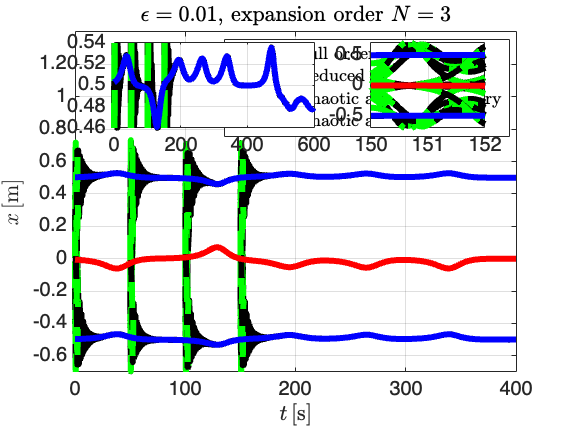

hold(ax1, 'on' );
hold on 
fp3 =plot(ax1,alphaTOG/epsilon,XIU(:,indexR),'-','LineWidth',3,'color',[1 0 0 0.3]);
hold on 
fp4 = plot(ax1,alphaTOG/epsilon,XISP(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3]);
hold on 
plot(ax1,alphaTOG/epsilon,XISM(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3]);
legend([fp1 fp2 fp3 fp4],'Full order model','Reduced order model','Chaotic anchor trajectory','Chaotic attractors','Interpreter','latex','Location','best')

hold(ax2, 'on' );
hold on
plot(ax2,alphaTOG/epsilon,XIU(:,indexR),'-','LineWidth',3,'color',[1 0 0 0.3]);
hold on 
plot(ax2,alphaTOG/epsilon,XISP(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3]);
hold on 
plot(ax2,alphaTOG/epsilon,XISM(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3]);
% axis([0,750,0.97,1.025])

hold(ax3, 'on' );
hold on
plot(ax3,alphaTOG/epsilon,XIU(:,indexR),'-','LineWidth',3,'color',[1 0 0 0.3]);
hold on 
plot(ax3,alphaTOG/epsilon,XISP(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3]);
hold on 
plot(ax3,alphaTOG/epsilon,XISM(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3]);

% axis([0,0.8,-1.2,1.2])


% origUnits = fig.Units;
% fig.Units = fig.PaperUnits;
% fig.PaperSize = fig.Position(3:4);
% fig.Units = origUnits;
% exportgraphics(fig, 'e008xcdot_slow.pdf');

% NMTEavg = sum(NMTET)/6;

% fig1 = figure
% fontsize(fig1, 20, "points")
% set(gcf,'color','w');
% box on
% grid on ;
% ax1 = gca;
% for ind = 1:6
%   plot(ax1,tSP,F_net(ind,:),'-','LineWidth',3,'color',[0 0 0 0.5])
% hold on 
%   
% end    
% hold on 
% plot(ax1,tSP,epsilon*ones(1,max(size(tSP))),'-','LineWidth',3,'color',[1 0 0 0.3])
% 
% save('NMTE0.008_3',"NMTEavg")
% set(fig, 'Units' , 'Inches' );
% pos = get(fig, 'Position' );
% set(fig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(fig, 'rail_x_slow_clarity.pdf' , '-dpdf' , '-r300' )

% set(fig, 'Units' , 'Inches' );
% pos = get(fig, 'Position' );
% set(fig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(fig, 'mixed_mode_error_force.pdf' , '-dpdf' , '-r300' )


Plot SSM snapshot:

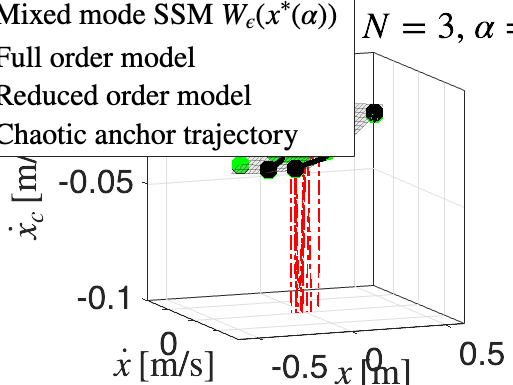

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [20×20 double]
           YData: [20×20 double]
           ZData: [20×20 double]
           CData: [20×20 double]

  Show all properties


hFig = figure('DefaultAxesFontSize',20);                       % Bring up new figure
% imshow('board.tif','Border','tight') % The axes will fill up the entire figure as much as possible without changing aspect ratio.
% hFig.WindowState = 'maximized';
pause(0.5)
delta = 0.5;
tl =  30;
% tl = 1000
clear movieVector

nssm = 20;
m0=1;
m1 = 1;

m2 = 1;
m3 = 1;
spand = 50;
ind = 1;
for j = to(3)+10:to(3)+10 %1:20:to(3)+300 %to(4)+10:to(4)+10%1:spand:17000 % 1:100:70000%:1200%(max(size(t_sol))-tl)
i = j+0;
     clf
% subplot(2, 2, [1 3])
    
     plotdofs = [2 4 3]; 
    
     x = linspace(-1,1,nssm);
     y = linspace(-0.5,0.5,nssm);
     [X,Y]=meshgrid(x,y);
    
     Z = X+1i*Y;
     t_ssm = ones(1,nssm*nssm)*store_Traj{1,1}(j+tl);

     [ZZ,modalZ,Net_Solz] = compute_SSM_phy(XI_0U,XI_1U,XI_2U,XI_3U,t_ssm,Z(:).',epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);

  
     Z1 = reshape(ZZ(plotdofs(1),:),nssm,nssm);
     Z2 = reshape(ZZ(plotdofs(2),:),nssm,nssm);
     Z3 = reshape(ZZ(plotdofs(3),:),nssm,nssm);


     h = surf(Z1,Z2,Z3)
     h.EdgeColor = [0 0 0];
     h.FaceColor = [.7 .7 .7];
     h.FaceAlpha = 0.3;
     h.EdgeAlpha = 0.3;
     hold on 

       plot3(store_Traj{1,2}(1:30:end,plotdofs(1)),store_Traj{1,2}(1:30:end,plotdofs(2)),store_Traj{1,2}(1:30:end,plotdofs(3)),'-.','LineWidth',1,'Color',[1 0 0 0.5]);
       hold on 
%       plot3(store_Traj{1,3}(1:50:end,plotdofs(1)),store_Traj{1,3}(1:50:end,plotdofs(2)),store_Traj{1,3}(1:50:end,plotdofs(3)),'-.','LineWidth',1,'Color',[0 0 1 0.5]);
%       hold on 
%       plot3(store_Traj{1,4}(1:50:end,plotdofs(1)),store_Traj{1,4}(1:50:end,plotdofs(2)),store_Traj{1,4}(1:50:end,plotdofs(3)),'-.','LineWidth',1,'Color',[0 0 1 0.5]);
%       hold on 
     if (j+tl >= to(1))
         marker = 2;
       for nTraj = 1:16
             
             if m0+tl <=40
                 ft = plot3(store_Traj{marker,4}(m0:m0+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m0:m0+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m0:m0+tl,plotdofs(3)+(nTraj-1)*4),'-','LineWidth',3,'Color',[0 0 0 0.5]);
            hold on 
            rt = plot3((store_Traj{marker,2}(m0:m0+tl,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m0:m0+tl,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m0:m0+tl,plotdofs(3)+(nTraj-1)*4)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
            hold on 
             plot3((store_Traj{marker,2}(m0+tl,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m0+tl,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m0+tl,plotdofs(3)+(nTraj-1)*4)),'.','MarkerSize',30,'Color','green');
            hold on
             plot3(store_Traj{marker,4}(m0+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m0+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m0+tl,plotdofs(3)+(nTraj-1)*4),'.','MarkerSize',30,'Color','black');
            hold on
            elseif m0<=40
                end1=40;
                ft = plot3(store_Traj{marker,4}(m0:end1,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m0:end1,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m0:end1,plotdofs(3)+(nTraj-1)*4),'-','LineWidth',3,'Color',[0 0 0 0.5]);
            hold on 
                
                rt = plot3((store_Traj{marker,2}(m0:end1,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m0:end1,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m0:end1,plotdofs(3)+(nTraj-1)*4)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
                hold on
                
            end   
            
           
            
       end  
            if m0<=40 
                m0 = m0 + 1;
            else
                m0 = m0+20;
            end  
        

     end 
     if   (j+tl >= to(2))
           marker = 3;
       for nTraj = 1:16
             ft = plot3(store_Traj{marker,4}(m1:m1+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m1:m1+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m1:m1+tl,plotdofs(3)+(nTraj-1)*4),'-','LineWidth',3,'Color',[0 0 0 0.5]);
            hold on 
           if m1+tl <=40
            rt = plot3((store_Traj{marker,2}(m1:m1+tl,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m1:m1+tl,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m1:m1+tl,plotdofs(3)+(nTraj-1)*4)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
            hold on 
             plot3((store_Traj{marker,2}(m1+tl,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m1+tl,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m1+tl,plotdofs(3)+(nTraj-1)*4)),'.','MarkerSize',30,'Color','green');
            hold on
            elseif m1<=40
                end1=40;
                rt = plot3((store_Traj{marker,2}(m1:end1,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m1:end1,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m1:end1,plotdofs(3)+(nTraj-1)*4)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
                hold on
            end 
         hold on 
        plot3(store_Traj{marker,4}(m1+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m1+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m1+tl,plotdofs(3)+(nTraj-1)*4),'.','MarkerSize',30,'Color','black');
       hold on
       end 
       
       if m1<=40 
                m1 = m1 + 1;
       else
                m1 = m1+20;
       end  
     end  
     if     (j+tl >= to(3))
          marker = 4;
       for nTraj = 1:16
            ft = plot3(store_Traj{marker,4}(m2:m2+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m2:m2+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m2:m2+tl,plotdofs(3)+(nTraj-1)*4),'-','LineWidth',3,'Color',[0 0 0 0.5]);
            hold on 
            if m2+tl <=40
            rt = plot3((store_Traj{marker,2}(m2:m2+tl,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m2:m2+tl,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m2:m2+tl,plotdofs(3)+(nTraj-1)*4)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
            hold on 
             plot3((store_Traj{marker,2}(m2+tl,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m2+tl,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m2+tl,plotdofs(3)+(nTraj-1)*4)),'.','MarkerSize',30,'Color','green');
            hold on
            elseif m2<=40
                end1=40;
                rt = plot3((store_Traj{marker,2}(m2:end1,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m2:end1,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m2:end1,plotdofs(3)+(nTraj-1)*4)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
                hold on
            end
            hold on 
            plot3(store_Traj{marker,4}(m2+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m2+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m2+tl,plotdofs(3)+(nTraj-1)*4),'.','MarkerSize',30,'Color','black');
            hold on
       end 
        if m2<=40 
                m2 = m2 + 1;
       else
                m2 = m2+20;
       end 
       
     end
%      if (j+tl >= to(4))
%           marker = 5;
%        for nTraj = 1:16
%             ft = plot3(store_Traj{marker,4}(m3:m3+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m3:m3+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m3:m3+tl,plotdofs(3)+(nTraj-1)*4),'-','LineWidth',3,'Color',[0 0 0 0.5]);
%             hold on 
%              if m3+tl <=100
%             rt = plot3((store_Traj{marker,2}(m3:m3+tl,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m3:m3+tl,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m3:m3+tl,plotdofs(3)+(nTraj-1)*4)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
%             hold on 
%              plot3((store_Traj{marker,2}(m3+tl,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m3+tl,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m3+tl,plotdofs(3)+(nTraj-1)*4)),'.','MarkerSize',30,'Color','green');
%             hold on
%             elseif m3<=100
%                 end1=100;
%                 rt = plot3((store_Traj{marker,2}(m3:end1,plotdofs(1)+(nTraj-1)*4)),(store_Traj{marker,2}(m3:end1,plotdofs(2)+(nTraj-1)*4)),(store_Traj{marker,2}(m3:end1,plotdofs(3)+(nTraj-1)*4)),'-','LineWidth',3,'Color',[0 1 0 0.5]);
%                 hold on
%             end
%         
%             hold on 
%             plot3(store_Traj{marker,4}(m3+tl,plotdofs(1)+(nTraj-1)*4),store_Traj{marker,4}(m3+tl,plotdofs(2)+(nTraj-1)*4),store_Traj{marker,4}(m3+tl,plotdofs(3)+(nTraj-1)*4),'.','MarkerSize',30,'Color','black');
%             hold on
%        end 
%         
%        m3 = m3 + spand;
% 
%      end 
%      hold on
      unst = plot3(store_Traj{1,2}(j:j+tl,plotdofs(1)),store_Traj{1,2}(j:j+tl,plotdofs(2)),store_Traj{1,2}(j:j+tl,plotdofs(3)),'-','LineWidth',3,'Color',[1 0 0 0.5]);
%       hold on 
%       st = plot3(store_Traj{1,3}(j:j+tl,plotdofs(1)),store_Traj{1,3}(j:j+tl,plotdofs(2)),store_Traj{1,3}(j:j+tl,plotdofs(3)),'-','LineWidth',3,'Color',[0 0 1 0.5]);
%       hold on 
%       plot3(store_Traj{1,4}(j:j+tl,plotdofs(1)),store_Traj{1,4}(j:j+tl,plotdofs(2)),store_Traj{1,4}(j:j+tl,plotdofs(3)),'-','LineWidth',3,'Color',[0 0 1 0.5]);
%       
%       hold on
       plot3(store_Traj{1,2}(j+tl,plotdofs(1)),store_Traj{1,2}(j+tl,plotdofs(2)),store_Traj{1,2}(j+tl,plotdofs(3)),'.','MarkerSize',30,'Color','red');
      hold on 
%       plot3(store_Traj{1,3}(j+tl,plotdofs(1)),store_Traj{1,3}(j+tl,plotdofs(2)),store_Traj{1,3}(j+tl,plotdofs(3)),'.','MarkerSize',30,'Color',[0,0,1]);
%       hold on 
%       plot3(store_Traj{1,4}(j+tl,plotdofs(1)),store_Traj{1,4}(j+tl,plotdofs(2)),store_Traj{1,4}(j+tl,plotdofs(3)),'.','MarkerSize',30,'Color',[0,0,1]);
%       
        rt = plot3(0,0,-0.01,'-','LineWidth',3,'Color',[0 1 0 0.5]);
    xl = xlabel('$x \,[$m$]$','Interpreter','latex');
%      xl.Position = [0.0112 -2.3821 -0.0445+0.002];
        xl.Position=[-0.0878 -3.2810 -0.1003];
    xl.HorizontalAlignment = 'center';

    yl =  ylabel('$\dot{x} \,[$m/s$]$','Interpreter','latex');
%       yl.Position = [-0.5850 0.3355 -0.0449+0.001];
yl.Position = [-0.8241 -0.5074 -0.1033];
%     yl.Position = [-0.6460 1 -0.2637];

    yl.HorizontalAlignment = 'center';

    zl = zlabel('$\dot{x}_c \,[$m/s$]$','Interpreter','latex');
    zl.HorizontalAlignment = 'center';

%        rt = plot3(0,0,-0.1,'-','LineWidth',3,'Color',[0 1 0 0.5]);
            hold on 
 title_string = strcat('$\epsilon = ',num2str(epsilon),'$, expansion order $N = 3$, $\alpha =',num2str(epsilon*round(t_ssm(1,1),4),'%4.4f'),'$');
 title(title_string,'Interpreter','latex')
       
%          legend('SSM - $W_{\epsilon}(x_{\epsilon}(\alpha))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 3)$','$O(\epsilon^3)$ anchor trajectory','Full order model','Reduced order model','$O(\epsilon^3)$ anchor trajectory [$x_{\epsilon}(\alpha = \epsilon t)$]','Interpreter','latex','location','northwest')
%        legend([h ft rt unst st],'SSM - $W_{\epsilon}(x_{\epsilon}(\alpha))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 3)$','Full order model','Reduced order model','Anchor trajectory [$x_{\epsilon}(\alpha = \epsilon t)$]','Stable solutions','Interpreter','latex','location','northwest')
    l = legend([h ft rt unst],'Mixed mode SSM $W_{\epsilon}(x^{*}(\alpha))$','Full order model','Reduced order model','Chaotic anchor trajectory','Interpreter','latex','location','northwest');
l.Position = [0.0331 0.7053 0.4769 0.2188];
       %       legend([h ft unst st],'SSM - $W_{\epsilon}(x_{\epsilon}(\alpha))$ $O(\epsilon^{k_1} \mathbf{u}^{\mathbf{k}_2}, k_1 + |k_2| = 3)$','Full order model','$O(\epsilon^3)$ anchor trajectory [$x_{\epsilon}(\alpha = \epsilon t)$]','$O(\epsilon^3)$ stable solutions','Interpreter','latex','location','northwest')

%     string = strcat('\alpha = ',num2str(round(epsilon*t_sol(j+tl),2),'%4.2f' ),', \epsilon = 0.008');
%     if (round(epsilon*t_sol(j+tl),2)) >=1
%      string = strcat('{\color{blue}\alpha = ',num2str(round(epsilon*t_sol(j+tl),2),'%4.2f' ),',}\epsilon = 0.008');
%      title(string);
%     else
%      title(string);
%     end   
%      axis([-0.7,0.7,-1.5,1.5,-0.16,0.02])
%     view(-79,7)
set(gcf,'color','white')
set(hFig, 'Units' , 'Inches' );
pos = get(hFig, 'Position' );
set(hFig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
set(gcf,'Renderer','painters')


    grid on
    box on
%            daspect([1,1,1])
%   axis([-1,1,-2,2,-0.06,0])
 view(-22,10)
axis([-0.6,0.6,-1.8,1.8,-0.1,0])
% view(-39,43)
set(gcf,'color','white')
    figssm = gcf;

movieVector(ind) = getframe(hFig);
    
    ind = ind +1;

end


% myWriter = VideoWriter('SSM_Rail_solutions_Adiabatic_med_edit','MPEG-4');
% myWriter.FrameRate = 10;
% 
% open(myWriter);
% writeVideo(myWriter,movieVector);
% close(myWriter);

% set(hFig, 'Units' , 'Inches' );
% pos = get(hFig, 'Position' );
% set(hFig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(hFig, 'ssm_rail_slow_snap1.pdf' , '-dpdf')

% set(fig, 'Units' , 'Inches' );
% pos = get(fig, 'Position' );
% set(fig, 'PaperPositionMode' , 'Auto' , 'PaperUnits' , 'Inches' , 'PaperSize' ,[pos(3), pos(4)])
% set(gcf,'Renderer','painters')
% print(fig, 'forcing_slow.pdf' , '-dpdf')
% 

% plot3(SP_Traj1(plotdofs(1),j:j+tl),SP_Traj1(plotdofs(2),j:j+tl),SP_Traj1(plotdofs(3),j:j+tl),'-','LineWidth',3,'Color',[0 0 0 0.5]);
%      hold on
%      plot3(shift_traj(plotdofs(1),j:j+tl),shift_traj(plotdofs(2),j:j+tl),shift_traj(plotdofs(3),j:j+tl),'-','LineWidth',3,'Color',[1 0 0 0.5]);
%      hold on
%      plot3(SolutionA(plotdofs(1),j:j+tl),SolutionA(plotdofs(2),j:j+tl),SolutionA(plotdofs(3),j:j+tl),'-','LineWidth',3,'color',[0,0,1,0.8])
%      hold on
%      plot3(shift_traj(plotdofs(1),j+tl),shift_traj(plotdofs(2),j+tl),shift_traj(plotdofs(3),j+tl),'.','MarkerSize',30,'Color','red');
%      hold on
%      plot3(SP_Traj1(plotdofs(1),j+tl),SP_Traj1(plotdofs(2),j+tl),SP_Traj1(plotdofs(3),j+tl),'.','MarkerSize',30,'Color','black');
%      hold on
%      plot3(SolutionA(plotdofs(1),j+tl),SolutionA(plotdofs(2),j+tl),SolutionA(plotdofs(3),j+tl),'.','MarkerSize',30,'Color',[0,0,1]);
%      hold on

Computing the non-dimensional foricng speed. 

c = 0.3;
k = 1;
a = 0.5;
g = 9.8;
m = 1;
Mf = 4;
cf = 0.3;
scale = 10*a^3;%2*a^3;
Sc = scale;
K = -[-k,k*m/(m+Mf);k*m/(m+Mf),4*a^2*m*g/scale-k*m^2/(m+Mf)^2];
C = -[-c,c*m/(m+Mf);c*m/(m+Mf),-cf-c*m^2/(m+Mf)^2];
M = [m+Mf,0;0,m*Mf/(m+Mf)];

F_I_net = [];

fig = figure

fig =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [476 460 560 420]
       Units: 'pixels'

  Show all properties


% fontsize(fig, 20, "points")
% set(gcf,'color','w');
% box on
% grid on ;
% axis([0,500,-4,7])
% ax1 = gca;
% ax2 = axes( 'Position' ,[.2 .7 .35 .2]);
% box on
% grid on ;
NMTET = [];
load('Solution_Unstable.mat','XI_0U','XI_1U','XI_2U','XI_3U');
load('Solution_stablem.mat','XI_0Sm','XI_1Sm','XI_2Sm','XI_3Sm');
load('Solution_stablep.mat','XI_0Sp','XI_1Sp','XI_2Sp','XI_3Sp');


% zo = [0.3*exp(-1i*pi/2),0.3*exp(1i*pi/2),0.5*exp(-1i*pi/2),0.5*exp(1i*pi/2),0.4*exp(1i*0.5),0.4*exp(-1i*0.5)];
% zo = [6.2*exp(-1i*pi/2),1.2*exp(1i*pi/2),1*exp(-1i*pi/2),1*exp(1i*pi/2),0.8*exp(1i*0.5),0.1*exp(-1i*0.5)];
nssm = 20;
 x = linspace(-1,1,nssm);
     [X,Y]=meshgrid(x);
%      Z = RHO.*exp(1i*Theta);
     Z = X+1i*Y;
     Ratio_Net = zeros(nssm,nssm);
           Net1 = zeros(nssm,nssm);
Net2 = zeros(nssm,nssm);

for ind = 1:nssm
    for indk = 1:nssm

epsilon = 0.0058;

alphaT = linspace(0,6,10000);



ctspan = alphaT/(epsilon);



ROM=@(t,z) rom_temp_model_adiabatic_rail(t,z,SSM_Coeff_A_2,SSM_Coeff_A_1,xi_20,xi_21,xi_41,xi_22,xi_42,Valpha,V,A,Force_Lorenz,Dalpha,epsilon,a,g,c,cf,Mf,m,k,Sc);

q0 = Z(ind,indk);
epsilon = 0.01;
[y0,model0,Net_Sol0] = compute_SSM_phy(XI_0U,XI_1U,XI_2U,XI_3U,ctspan(1),q0,epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);

% IC = [real(q0);imag(q0)];
% 
% tic 
% [t_sol,ROM_sol] = ode45(ROM,ctspan,IC);
% toc

% [y,modal,Net_Sol] = compute_SSM_phy(XI_0U,XI_1U,XI_2U,XI_3U,t_sol,(ROM_sol(:,1)+1i*ROM_sol(:,2)).',epsilon,SSM_Coeff_A_2,SSM_Coeff_A_1,Valpha,V,A,Force_Lorenz,Dalpha);


GH = @(t,y) Full_Order_Model_PM(t,y,Force_Lorenz,0,c,k,a,g,m,Mf,cf,scale);
tic
IC = y0;
[tSP,Full_Traj] = ode45(GH,ctspan,IC);
toc







% SolutionA = epsilon*xi_full_eval(ctspan.') +epsilon^3*xi_full_eval3(ctspan.')+epsilon^5*xi_full_eval5(ctspan.');
% FullS = @(t,y) full_system(t,y,epsilon,Force_Lorenz,m1,m2,Mf,kf,k,c,cf,gamma);
% 
% tic
% IC =  y0;
% [tSP,SP_Traj] = ode45(FullS,ctspan,IC);
% toc


y = Full_Traj.';
F_an = (abs(Force_Lorenz(epsilon*tSP))).';
% F_an = trapz(tSP,F_an)/(max(tSP)*mean(F_an));

F_spring = K*[y(1,:);y(2,:)];
F_damper = C*[y(3,:);y(4,:)];
F_nonlinear = [0*y(1,:);4*g*m*y(2,:).^3/scale + 16*m*a^4*y(2,:).*y(4,:).^2/scale^2];
F_total = F_spring + F_damper + F_nonlinear;
F_net = sqrt(sum(F_total.^2));
[dXdF_net, Xtrunc_net,tSp_red] = ftd(F_net, tSP.');
[dXdF_an, Xtrunc_an,tSp_red] = ftd(F_an, tSP.');
F_I_net = [F_I_net;trapz(tSP,F_an./F_net)/(max(tSP))];
Net1(ind,indk) = trapz(tSp_red,abs(dXdF_an.'))/(max(tSP));
 Net2(ind,indk) = (trapz(tSp_red,abs(dXdF_net.'))/(max(tSP)));

Ratio_Net(ind,indk) = trapz(tSp_red,abs(dXdF_an.'))/(max(tSP))./(trapz(tSp_red,abs(dXdF_net.'))/(max(tSP)));

% Ratio_Net(ind,indk) = trapz(tSP,F_an./F_net)/(max(tSP));

%  hold(ax1, 'on' );
% indexR = 3;
% plot(ax1,tSP,SP_Traj(:,indexR),'-','LineWidth',3,'color','black')
% hold on 
% plot(ax1,tSP,y(indexR,:),'--','LineWidth',3,'color','red')
% hold on 
% plot(ax1,tSP,SolutionA(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3])
% hold on 
% xlabel(ax1,'$t \,[$s$]$','Interpreter','latex');
% ylabel(ax1,'$x_{c} \,[$m$]$','Interpreter','latex');
% legend(ax1,'Full Order Model','Reduced Order Model $O(5)$','Anchor Trajectory','Interpreter','latex')
% title(ax1,'\epsilon = 0.5, reduced order model performance')
% hold on
% 
% grid on ;
% 
% % ax2 = axes( 'Position' ,[.2 .7 .5 .2])
% hold(ax2, 'on' );
% hold on 
% plot(ax2,tSP,SP_Traj(:,indexR),'-','LineWidth',3,'color','black')
% hold on 
% plot(ax2,tSP,y(indexR,:),'--','LineWidth',3,'color','red')
% hold on 
% plot(ax2,tSP,SolutionA(:,indexR),'-','LineWidth',3,'color',[0 0 1 0.3])
% hold on 
% xlabel(ax2,'$t \,[$s$]$','Interpreter','latex');
% ylabel(ax2,'$x_{c} \,[$m$]$','Interpreter','latex');
% axis([0,80,-4,4])
% grid on ;
% 
% NMTE = sum(sqrt(sum((y.' - SP_Traj).^2,2)))/(sqrt(max(sum((SP_Traj).^2,2)))*max(size(ctspan)));
% NMTET = [NMTET,NMTE];
    end
end

Elapsed time is 0.336655 seconds.
Elapsed time is 0.282585 seconds.
Elapsed time is 0.270349 seconds.
Elapsed time is 0.288483 seconds.
Elapsed time is 0.300707 seconds.
Elapsed time is 0.315723 seconds.
Elapsed time is 0.302622 seconds.
Elapsed time is 0.287077 seconds.
Elapsed time is 0.277305 seconds.
Elapsed time is 0.277618 seconds.
Elapsed time is 0.298933 seconds.
Elapsed time is 0.301026 seconds.
Elapsed time is 0.273672 seconds.
Elapsed time is 0.285234 seconds.
Elapsed time is 0.277325 seconds.
Elapsed time is 0.303704 seconds.
Elapsed time is 0.305911 seconds.
Elapsed time is 0.300084 seconds.
Elapsed time is 0.301173 seconds.
Elapsed time is 0.293238 seconds.
Elapsed time is 0.297544 seconds.
Elapsed time is 0.280807 seconds.
Elapsed time is 0.292325 seconds.
Elapsed time is 0.298134 seconds.
Elapsed time is 0.293227 seconds.
Elapsed time is 0.293923 seconds.
Elapsed time is 0.268594 seconds.
Elapsed time is 0.267527 seconds.
Elapsed time is 0.287901 seconds.
Elapsed time i

% origUnits = fig.Units;
% fig.Units = fig.PaperUnits;
% fig.PaperSize = fig.Position(3:4);
% fig.Units = origUnits;
% exportgraphics(fig, 'e008xcdot_slow.pdf');

% bp = mean(Ratio_Net(:));
bp = mean( Net1(:))./mean( Net2(:));
disp(['Forcing speed = ',num2str(bp)]);

Forcing speed = 1.2101



NMTEavg = sum(NMTET)/6;

% fig = figure
% P = pcolor(X,Y,Ratio_Net);
% P.EdgeColor = 'none';
% colormap copper
% colorbar 
% xlabel('$u_1$','Interpreter','latex');
% ylabel('$u_2$','Interpreter','latex');
% 
% title_string = strcat('$\displaystyle \frac{\overline{|\frac{d}{dt}|F_{ext}|_{t_0}^{t_f}(x_0)|}}{\overline{|\frac{d}{dt}|F_{int}|_{t_0}^{t_f}(x_0)|}}$, $\epsilon = ',num2str(epsilon),'$');
% 
% 
% title(title_string,'Interpreter','latex')
% 
% figure 
% contour(X,Y,Ratio_Net)
% colorbar